close all
clear
clc

syms x y z real
syms p_ref real
syms mu L R U mu_m eta Ha real positive

X=[x,y];

v=[3/2*U*2*(1-cosh(y/R*Ha)/cosh(Ha))*(Ha*tanh(Ha))^(-1)
   0]

$$v = \left[\begin{array}{c} -\frac{3\,U\,\left(\frac{\cosh\left(\frac{\mathrm{Ha}\,y}{R}\right)}{\cosh\left(\mathrm{Ha}\right)}-1\right)}{\mathrm{Ha}\,\tanh\left(\mathrm{Ha}\right)}\\ 0 \end{array}\right]$$

p=p_ref+3*mu*L*U/R^2*(1-x/L)-9/2*mu*U^2/eta*(sinh(y/R*Ha)/sinh(Ha)-y/R)^2*Ha^(-2)

$$p = p_{\mathrm{ref}}-\frac{3\,L\,U\,\mu \,\left(\frac{x}{L}-1\right)}{R^{2}}-\frac{9\,U^{2}\,\mu \,{\left(\frac{y}{R}-\frac{\sinh\left(\frac{\mathrm{Ha}\,y}{R}\right)}{\sinh\left(\mathrm{Ha}\right)}\right)}^{2}}{2\,{\mathrm{Ha}}^{2}\,\eta }$$

b=[3*sqrt(mu*mu_m/eta)*U*(sinh(y/R*Ha)/sinh(Ha)-y/R)*Ha^(-1)
   sqrt(mu*mu_m*eta)/R*Ha]

$$b = \left[\begin{array}{c} -\frac{3\,U\,\sqrt{\mu }\,\sqrt{\mu_{m}}\,\left(\frac{y}{R}-\frac{\sinh\left(\frac{\mathrm{Ha}\,y}{R}\right)}{\sinh\left(\mathrm{Ha}\right)}\right)}{\mathrm{Ha}\,\sqrt{\eta }}\\ \frac{\mathrm{Ha}\,\sqrt{\eta }\,\sqrt{\mu }\,\sqrt{\mu_{m}}}{R} \end{array}\right]$$

q=0

q = 0

f=0

f = 0

g=0

g = 0

% Check that residual R_v
sigma=mu*(mygradient(v,X)+transpose(mygradient(v,X)))-p*eye(2);
lorentz=cross([0;0;1/mu_m*mycurl(b,X)],[b;0]);
lorentz=lorentz(1:2);
R_v=simplify(-mydivergence(sigma,X)-lorentz-f)

$$R\_v = \left[\begin{array}{c} 0\\ 0 \end{array}\right]$$

% Check that residual R_p
R_p=simplify(mydivergence(v,X))

$$R\_p = 0$$

% Check that residual R_b
sigma_m=eta*(mygradient(b,X)+transpose(mygradient(b,X)))-q*eye(2);
R_b=eval(simplify(...
    +mydivergence(b*transpose(v)-v*transpose(b),X)...
    -mydivergence(sigma_m,X)-g))

R_b =      0
     0


% Check that residual R_q
R_q=simplify(mydivergence(b,X))

$$R\_q = 0$$

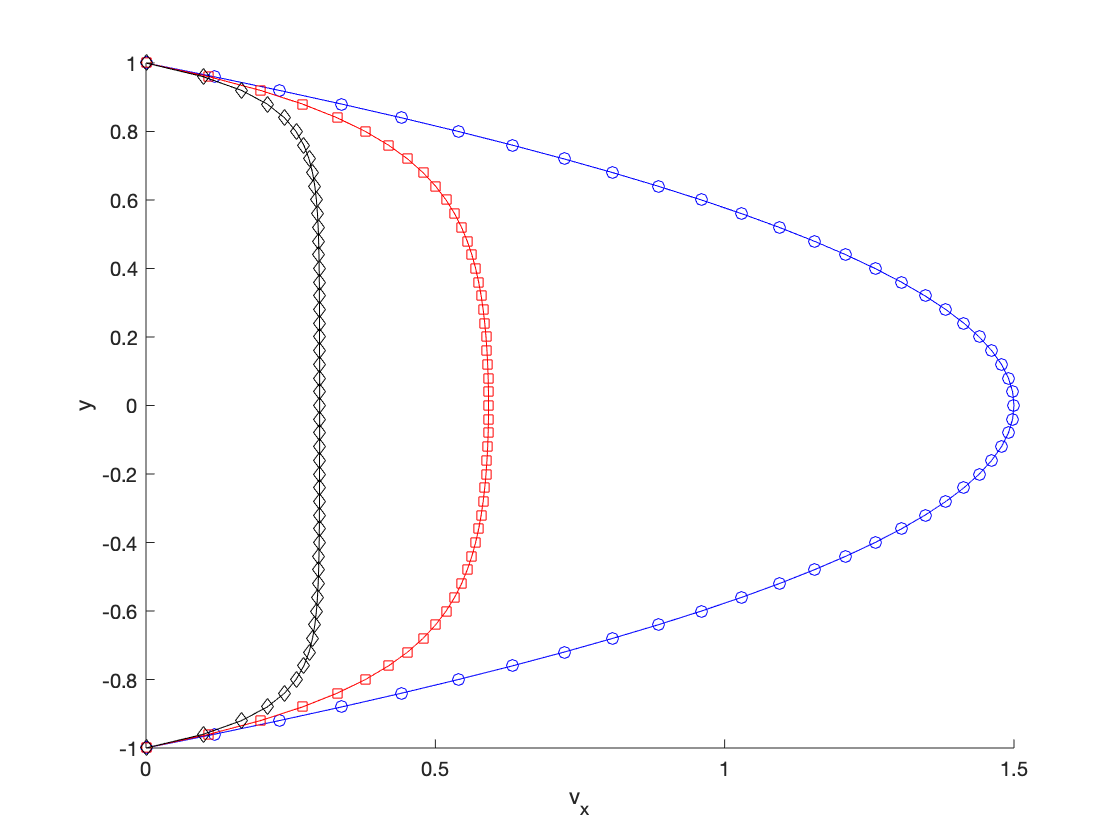

% Check
p_ref=0;
mu=1;
mu_m=1;
eta=1;
L=10;
R=1;
U=1;
y=linspace(-R,+R,51);
x=L/2*ones(size(y));
figure
hold on
Ha=0.01; plot(eval(v(1)),y,'b-o')
Ha=5;    plot(eval(v(1)),y,'r-s')
Ha=10;   plot(eval(v(1)),y,'k-d')
hold off
xlabel('v_x'); ylabel('y');

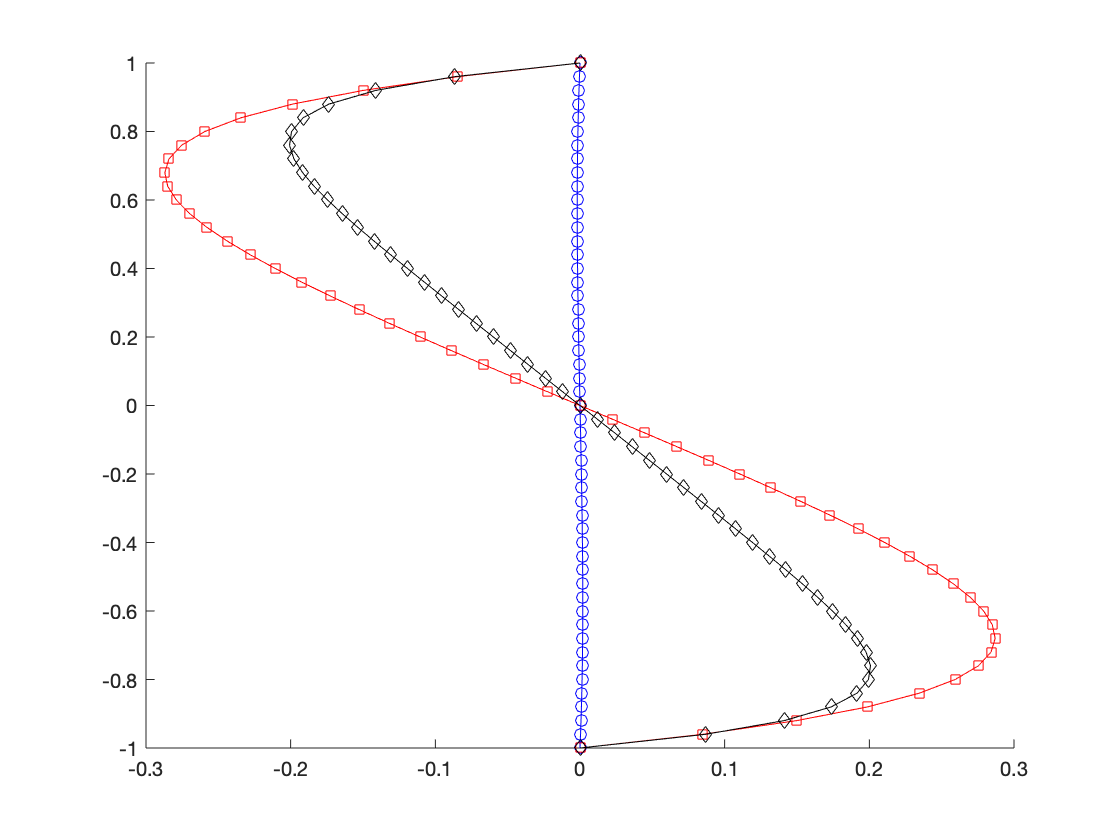

figure
hold on
Ha=0.01; plot(eval(b(1)),y,'b-o')
Ha=5;    plot(eval(b(1)),y,'r-s')
Ha=10;   plot(eval(b(1)),y,'k-d')
hold off